# Demonstrate enhancing contrast of 2D images

Grayscale image, enhancement 

pout = imread("tire.tif");
pout_imadjust = imadjust(pout);
pout_histeq = histeq(pout);
pout_adapthisteq = adapthisteq(pout);

Display output

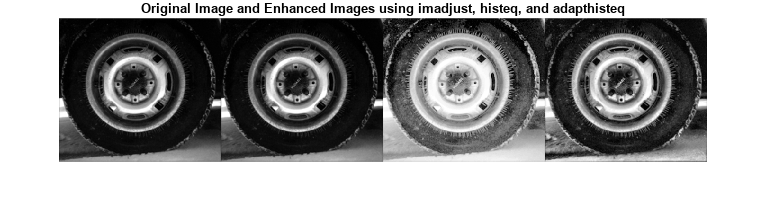

montage({pout,pout_imadjust,pout_histeq,pout_adapthisteq},"Size",[1 4]);
title("Original Image and Enhanced Images using imadjust, histeq, and adapthisteq");

Color Image

shadow = imread("lowlight_2.jpg");
shadow_lab = rgb2lab(shadow);

The values of luminosity span a range from 0 to 100. Scale the values to the range [0 1], which is the expected range of images with data type `double`.

max_luminosity = 100;
L = shadow_lab(:,:,1)/max_luminosity;

Perform the three types of contrast adjustment on the luminosity channel, and keep the a* and b* channels unchanged. Convert the images back to the RGB color space.

shadow_imadjust = shadow_lab;
shadow_imadjust(:,:,1) = imadjust(L)*max_luminosity;
shadow_imadjust = lab2rgb(shadow_imadjust);

shadow_histeq = shadow_lab;
shadow_histeq(:,:,1) = histeq(L)*max_luminosity;
shadow_histeq = lab2rgb(shadow_histeq);

shadow_adapthisteq = shadow_lab;
shadow_adapthisteq(:,:,1) = adapthisteq(L)*max_luminosity;
shadow_adapthisteq = lab2rgb(shadow_adapthisteq);

Display the original image and the three contrast adjusted images as a montage.

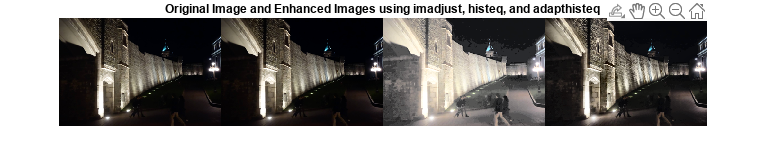

figure
montage({shadow,shadow_imadjust,shadow_histeq,shadow_adapthisteq},"Size",[1 4])
title("Original Image and Enhanced Images using " + ...
    "imadjust, histeq, and adapthisteq")

Segmenting

I = imread('autumn.tif');

I2 = imcrop(I,[75 68 130 112]);

Display original image and cropped image.

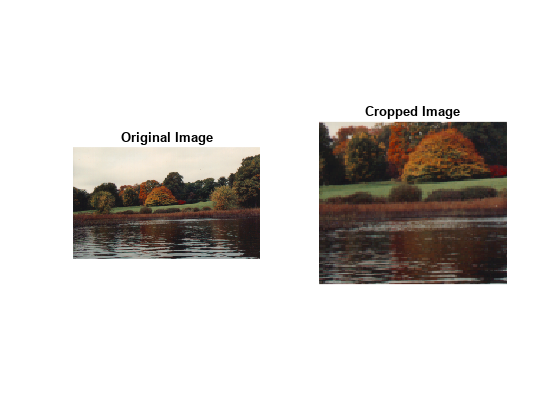

figure
subplot(1,2,1)
imshow(I)
title('Original Image')
subplot(1,2,2)
imshow(I2)
title('Cropped Image')